# Exploring Integration

## Introduction

The process of finding integrals is called **integration**. Along with differentiation, integration is a fundamental operation of calculus, and serves as a tool to solve problems in mathematics and physics involving the area of an arbitrary shape, the length of a curve, and the volume of a solid, among others.

In this activity we will learn how to use MATLAB to compute antiderivatives (when it is possible) and the definite integrals using the command [`int()`](https://au.mathworks.com/help/symbolic/sym.int.html).

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

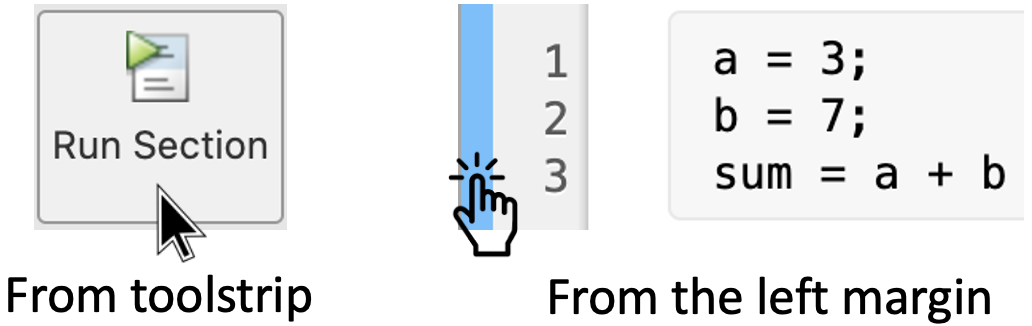

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Calculating antiderivatives

Recall that the *indefinite integral* is defined as


$$\int f(x)dx=F(x)+C$$


where $F(x)$ is an *antiderivative* of $f(x)$, that is, $F'(x)=f(x)$; and $C$ is an arbitrary real constant.

Unfortunately, MATLAB does not calculate the indefinite integral, which is the set of all possible antiderivatives. However, it can calculate symbolically a particular antiderivative of a given function using the command

[`int(expr, var)`](https://au.mathworks.com/help/symbolic/sym.int.html)

where [`expr`](https://au.mathworks.com/help/symbolic/sym.int.html#btybolt-expr) is the function defined as a symbolic expression and [`var`](https://au.mathworks.com/help/symbolic/sym.int.html#btybolt-var) is a symbolic variable.

For example, consider the functions

$f(x)=3x^2-2x-1$, $g(y)=\sin y$, and $h(t)=\cos(a\cdot t + b)$.

To calculate the antiderivative of each one of them, first we need to define them symbolically and then use the command `int()`. Thus, we have:

syms x y t a b            % Define symbolic variables

fun1 = 3*x^2 - 2*x - 1    % Define f
antiDer1 = int(fun1)      % Antiderivative of f

fun2 = sin(y)             % Define g
antiDer2 = int(fun2)      % Antiderivative of g

fun3 = cos(a*t + b)       % Define h
antiDer3 = int(fun3, t)   % Antiderivative of h. Here we specified the variable

Run this section to see the results. Also see what happens when you change the variable `t` to `a` or `b` in the last line of the code.

Recall also that integration is the inverse process to differentiation. Thus, if we wish to verify that the previous results are indeed antiderivatives of the functions $f,\;g$ and $h$, we just need differentiate them. This can be done with the command [`diff()`](https://au.mathworks.com/help/symbolic/diff.html). That is:

diff(antiDer1)
diff(antiDer2)
diff(antiDer3, t)    % Here we need to specify the variable

You can also verify this in your notebook.

### 1.1 Interpreting results from MATLAB

MATLAB relies on well-known integration methods (substitution, integration by parts, partial fractions, etc.) and sophisticated algorithms for computing antiderivatives (when it is possible). However, you **must carefully analyse** the results provided by MATLAB to use them appropriately. For example, consider the function

$f(x) = 3x^4-4x^3+x$.

You can easily verify that


$$F(x) =\displaystyle \frac{3}{4}x^4-\frac{4}{3}x^3+\frac{1}{2}x^2$$


is antiderivative of $f$. Now compare with the result provided by MATLAB:

syms x
f = 3*x^4-4*x^3+x;
antiDer = int(f)

Do you notice the differences? Are they the same antiderivatives? What do you think?

### 1. 2 Impossible indefinite integrals

Calculating indefinite integrals is a more complex process compared to calculating derivatives. In some cases, it is just an **impossible** task. We know this since 1830s thanks to French mathematician [Joseph Liouville](https://en.wikipedia.org/wiki/Liouville%27s_theorem_(differential_algebra)). For example, consider the function

$f(x)=x^x$.

If we use the command `int()` we get the output: $\displaystyle \int x^xdx$.

MATLAB cannot calculate an expression or formula for this antiderivative. Not even the most powerful computer could do it.

syms x
int(x^x)

Other well-known examples of indefinite integrals that are **impossible** to calculate are

$\displaystyle\int e^{-x^2}dx, \; \int \sin\left(x^2\right)dx, \;\int \cos\left(x^2\right)dx,\; \int \frac{\sin x}{x}dx$.

These are known as *non-elementary integrals*. However, some of them have been studied for many years by mathematicians and nowadays there exist numerical methods to define them, in particular for calculating definite integrals.

## 2. Calculating definite integrals

In order to find the value of the definite integral


$$\int_a^bf(x)dx$$


we just need to add the *interval of integration. *That is

`int(expr, var, a, b)`

Let's see how this works with a few examples.

### Example 1:

Let's find the value of the integral


$$\int_0^{\pi}\sin x \,dx$$


Thus, we write:

syms x
expr = sin(x)
int(expr,[0 pi])

Check this result is correct using the **Fundamental Theorem of Calculus**. That is, find an antiderivative $F=f'$ and then use the formula

$\displaystyle \int_a^bf(x)\,dx = F(b) - F(a)$.

### Example 2: 

Now let's evaluate the integral

$\displaystyle \int_0^{3\sqrt{3}/2}\frac{x^3}{(4x^2+9)^{3/2}} \,dx$.

One way to evaluate it is by using the method of substitution involving trigonometric identities. In MATLAB we just need to write:

syms x
expr = x^3/(4*x^2+9)^(3/2)
int(expr,[0 3*sqrt(3)/2])

## Remark!

Even though MATLAB can be very handy to compute antiderivatives and definite integrals, you still **must** 

- have a basic knowledge on how to calculate them using different methods of integration; and

- analyse carefully the results provided by MATLAB.

Keep in mind that *integration is more complicated task* and there is no computer that can help you in all possible cases. In this case, humans are better than computers!

## 3. Hands on practice

Let's practice what we just learned.

### Activity 1:

Calculate the antiderivatives of the following functions:

- 
$$\displaystyle \frac{\sin \sqrt{x}}{\sqrt{x}}$$


- 
$$2x\sin(3x)$$


- 
$$\cos^2 x$$


- 
$$x\sin\left(x^2\right) e^{x^2}$$


Write your code here:

Confirm your results by differentiating the obtained results. Write your code here:

### Activity 2:

Calculate the following definite integrals

$\displaystyle \int_{-1}^{1}\frac{1}{x} \,dx, \;  \int_{-1}^{0}\frac{1}{x} \,dx,$ and $\displaystyle \int_{0}^{1}\frac{1}{x}\, dx$

and analyse the results. Write your code here:

What do you notice? What can you say about the function $f(x)=1/x$? Find an interval $[a,b]$ where you can calculate the definite integral? 